# **垂直跳び　床反力パワーを計算**

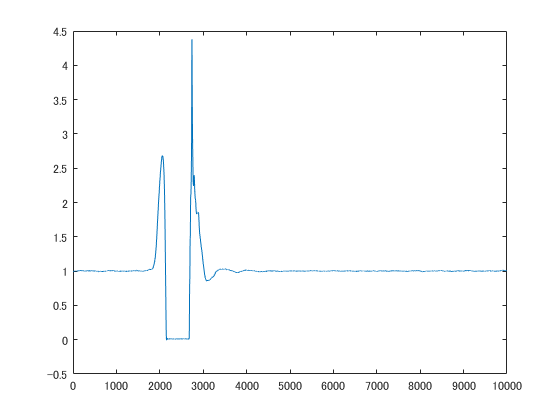

clear
close all
clc


% load 
fileName = 'DemoDataSJ' ;
load(fileName) ;

% *** 実験実習で測定計測したデータ を load***
fileName = 'Data_S08' ; % ←　被験者番号を指定する
load(fileName) ;

Data = DataStruct.CMJ(1) ; % ←　条件名・試行番号を指定する
grfs = Data.Forces ;
Markers = Data.Markers ;
% ****


% 図を作成して、床反力波形を確認
fz = grfs(:,3) + grfs(:,6) ;
plot(fz)

# **イベント検出**

時系列データから、イベントを検出する。

今回の目標は、ジャンプ動作の開始・離地・着地

## １．波形をプロットし、何を検出したいのかを整理する

教科書や論文に載っている図や記述を参考にするとよい

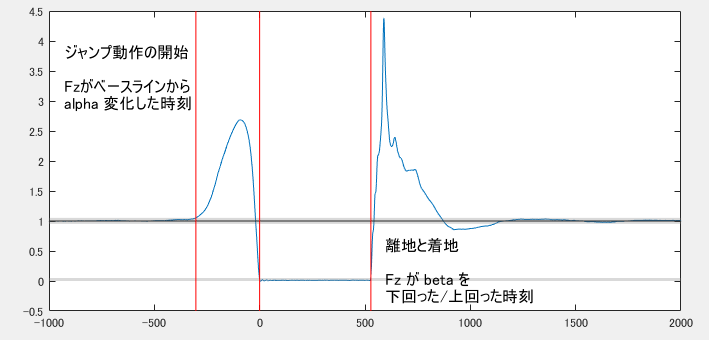

## イベント条件の定義

イベント検出のためには、イベント条件を、数式で定義する必要がある

※　プログラムは、fz(i) < beta を満たす最小の i は検出できるが、"離地の瞬間" は検出できない

※　コードインタプリターを用いればできるわけですが、プログラミング初心者は、いったん簡単な例でプログラムの挙動を理解した方が良いよいと思います。

ここでは、以下のように定義し、それに従い、コーディングしていきましょう

ジャンプ動作の開始：　Fz が、一定時間の間（winとする）、ベースラインから一定程度（alphaとする）乖離した時刻

離地と着地：　Fz が、一定時間の間（winとする）、一定の閾値（beta とする）を下回った/上回った時刻

※　alpha, beta は検出に用いたパラメータで、論文では、これらの値やアルゴリズムが書かれている

% 閾値パラメータ
% 閾値パラメータは、プログラム冒頭部などに、まとめて書いておいたが見やすいでしょう
alpha = 0.03 ; % ジャンプ動作開始　[per weight]
beta = 0.03 ; % 離地・着地 [per weight]
win = 50 ; % 時間条件 [ms] 　（一瞬だけ変化した、みたいな誤検出を防ぐことができる）

% イベント検出に共通しても用いる変数
n = length(fz) ;
baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                            %　なので、測定開始後1秒は静止していなければならない


## ジャンプ動作開始時刻


tOnsetJump = 1 ; % 変数の初期化

for ii = 2:n-win
    % 条件１　ジャンプ開始時刻の直前の fz は、ベースライン±αの範囲内にある
    criteria1 = fz(ii-1) < baseFz*(1+alpha) && fz(ii-1) > baseFz*(1-alpha) ;

    % 条件２　ジャンプ開始時刻から win (ms)間、 fz は、ベースライン±α の範囲外にある
    criteria2 = all(fz(ii:ii+win) >= baseFz*(1+alpha)) || all(fz(ii:ii+win) <= baseFz*(1-alpha)) ;

    if criteria1 && criteria2 % 上記の2条件を同時に満たす
        tOnsetJump = ii ;
        break % 1回検出したら、ループを抜ける
    end
    
end



## 離地と着地

% takeoff
for ii = 2:n-win
    if all( fz(ii:ii+win) < beta )
        tTakeOff = ii ;
        break
    end
end

% landing
for ii = tTakeOff:n-win
    if all( fz(ii:ii+win) > beta )
        tLanding = ii ;
        break
    end
end

flightTime = tLanding - tTakeOff

flightTime = 526

# **図を作成し、正しく検出できているか確認する**

プログラムが、思った通りの挙動ではない可能性を常に考えること。

誤ってノイズをイベントとして検出していたりした場合、アルゴリズムやパラメータを変更する必要があるかもしれない。

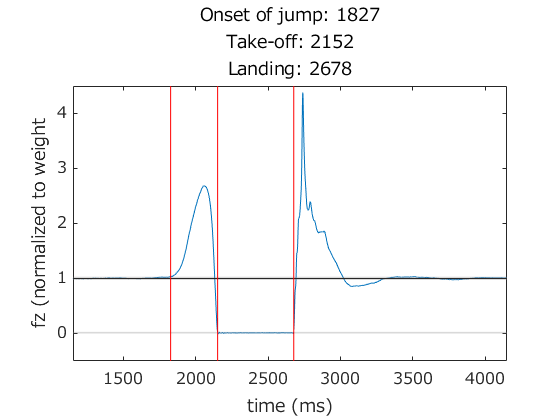

figure
plot(fz) ; % イベント検出に用いた時系列データ 

% イベント検出に用いた閾値を図示　（※　進矢の自作関数を使っています
lineplot(1, 'h', 'k') ; 
arealine([baseFz-alpha, baseFz+alpha], 'h') ; 
arealine([0, beta], 'h') ;

% 検出されたイベントを図示
lineplot([tOnsetJump, tTakeOff, tLanding], 'v', 'r') ;

% 表示範囲を設定
set(gca, 'xlim', [-1000, 2000]+tTakeOff)

% 凡例等
xlabel('time (ms)')
ylabel('fz (normalized to weight')
titleText = { sprintf('Onset of jump: %d', tOnsetJump) ;... % sprintf: 数値を文字列にフォーマットするときに用いる
              sprintf('Take-off: %d', tTakeOff) ;...
              sprintf('Landing: %d', tLanding) } ;
title(titleText)
set(gca, 'fontname', 'meiryo', 'fontsize', 12)

# **イベント検出を関数化する**

うまくイベントを検出できるプログラムが作成できたら、それを関数にしておくと、便利かもしれません

ジャンプ動作開始・離地・着地の3つのイベントは、以下の4つの変数があれば検出できます

fz, alpha, beta, win 

% うまく関数にすると、解析スクリプト本文が簡略に書ける
% 関数への入出力を構造体にしておくと、後で編集しやすい （分析項目が増えても対応できる）
Prm.Alpha = alpha ;
Prm.Beta = beta ;
Prm.Win = win ;

% この2行で書ける！
JumpEvent = detectJumpEvent(fz, Prm) ;

JumpEvent = フィールドをもつ struct :
    OnsetJump: 1827
      TakeOff: 2152
      Landing: 2678


figJumpEvent(fz, Prm, JumpEvent) ;

function JumpEvent = detectJumpEvent(fz, Prm)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    

    tOnsetJump = 0 ; % 変数の初期化
    for ii = 2:n-win
        % 条件１　ジャンプ開始時刻の直前の fz は、ベースライン±αの範囲内にある
        criteria1 = fz(ii-1) < baseFz*(1+alpha) && fz(ii-1) > baseFz*(1-alpha) ;
    
        % 条件２　ジャンプ開始時刻から win (ms)間、 fz は、ベースライン±α の範囲外にある
        criteria2 = all(fz(ii:ii+win) >= baseFz*(1+alpha)) || all(fz(ii:ii+win) <= baseFz*(1-alpha)) ;
    
        if criteria1 && criteria2 % 上記の2条件を同時に満たす
            tOnsetJump = ii ;
            break % 1回検出したら、ループを抜ける
        end
        
    end
    
    
    % takeoff
    tTakeOff = 0 ;
    for ii = 2:n-win
        if all( fz(ii:ii+win) < beta )
            tTakeOff = ii ;
            break
        end
    end
    
    % landing
    tLanding = 0 ;
    for ii = tTakeOff:n-win
        if all( fz(ii:ii+win) > beta )
            tLanding = ii ;
            break
        end
    end
    
    % output
    JumpEvent.OnsetJump = tOnsetJump ;
    JumpEvent.TakeOff = tTakeOff ;
    JumpEvent.Landing = tLanding ;
    
end


function figJumpEvent(fz, Prm, JumpEvent)
    
    % パラメータ
    alpha = Prm.Alpha ;
    beta = Prm.Beta ;
    win = Prm.Win ;
    
    % イベント検出に共通しても用いる変数
    n = length(fz) ;
    baseFz = mean(fz(1:1000)) ; % 最初の1秒の平均値をベースラインとする　
                                %　なので、測定開始後1秒は静止していなければならない
    
    % イベント時刻
    tOnsetJump = JumpEvent.OnsetJump ;
    tTakeOff = JumpEvent.TakeOff ;
    tLanding = JumpEvent.Landing ;
    
    % 図の作成
    figure
    plot(fz) ; % イベント検出に用いた時系列データ 
    
    % イベント検出に用いた閾値を図示　（※　進矢の自作関数を使っています
    lineplot(1, 'h', 'k') ; 
    arealine([baseFz-alpha, baseFz+alpha], 'h') ; 
    arealine([0, beta], 'h') ;
    
    % 検出されたイベントを図示
    lineplot([tOnsetJump, tTakeOff, tLanding], 'v', 'r') ;
    
    % 表示範囲を設定
    set(gca, 'xlim', [-1000, 2000]+tTakeOff)
    
    % 凡例等
    xlabel('time (ms)')
    ylabel('fz (normalized to weight')
    titleText = { sprintf('Onset of jump: %d', tOnsetJump) ;... % sprintf: 数値を文字列にフォーマットするときに用いる
                  sprintf('Take-off: %d', tTakeOff) ;...
                  sprintf('Landing: %d', tLanding) } ;
    title(titleText)
    set(gca, 'fontname', 'meiryo', 'fontsize', 12)

end
